
$$\begin{array}{l}
{\mathbf{y}}^{\prime } =\left\lbrack \begin{array}{c}
3y_1 \\
y_2 
\end{array}\right\rbrack \mathrm{mit}\;t\in \left\lbrack 0,10\right\rbrack ,h=1\;\mathrm{und}\;y\left(0\right)=1\\

\end{array}$$



$${\mathrm{F}}_{\textrm{euler}} \left(z\right)=h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)-\mathbf{z}\;=0\;\;\;\;\;\;\;\;\;$$


f = @(t,y) [3*y(1);y(2)];
df = @(t,y) [3,0;0,1];
ya = [1;1];
n=10;
tspan = [0,10];
tol = 10^(-8);
nmax= 100;

%[t,y_out] = impl_euler(f,tspan,ya,n,df,tol,nmax);

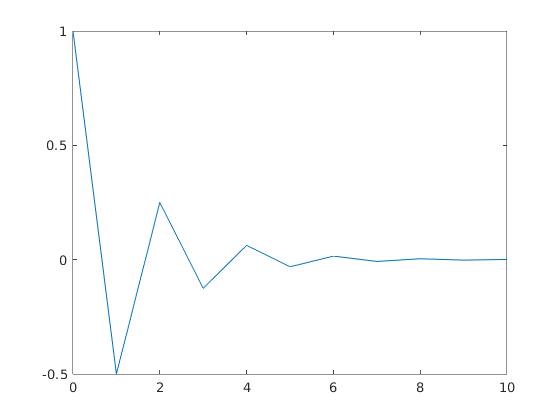

%plot(t,y_out)

Sei die Diffenrenzialgleichung

mit Hilfe von Worlframalpha bekommt man die Lösung


$${\mathit{\mathbf{y}}}^{\prime } \left(x\right)=\left\lbrack \begin{array}{c}
e^{-x} +e^{-x} x\\
e^{-x} 
\end{array}\right\rbrack$$



$$\begin{array}{l}
{\mathrm{F}}_{\textrm{euler}} \left(z\right)=h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)-\mathbf{z}\;=0\;\;\;\;\;\;\;\;\;\\
{\mathrm{F}}_{\textrm{euler}} \left(z\right)=h\;\mathbf{f}\left(t_{i+1} ,\left\lbrack \begin{array}{c}
y_1^{\left(i\right)} +z_1 \\
y_2^{\left(i\right)} +z_2 
\end{array}\right\rbrack \right)-\mathbf{z}\;=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;
\end{array}$$



$${\mathrm{F}}_{\textrm{euler}} \left(z\right)=h\;\left\lbrack \begin{array}{c}
-y_1^i -z_1 +y_2^i +z_2 \\
-y_1 -z_1 
\end{array}\right\rbrack -\mathbf{z}\;$$



$${\mathrm{F}}_{\textrm{euler}} \left(z\right)=h\;\left\lbrack \begin{array}{c}
-y_1^i -{2z}_1 +y_2^i +z_2 \\
-y_1 -z_1 -z_2 
\end{array}\right\rbrack$$



$${D\;\mathbf{F}}_{\textrm{euler}} \left(\mathbf{z}\right)=\left\lbrack \begin{array}{cc}
-2 & 1\\
-1 & -1
\end{array}\right\rbrack$$


für (i = 0)


$${\mathrm{F}}_{\textrm{euler}} \left(z\right)=\left\lbrack \begin{array}{c}
-1-{2z}_1 +1+z_2 \\
-1-z_1 -z_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-{2z}_1 +z_2 \\
-1-z_1 -z_2 
\end{array}\right\rbrack$$


f = @(y) [-y(1)+y(2);-y(1)];
syms z1 z2 y1 y2;
f([y1+z1;y2+z2])

$$ans = \left(\begin{array}{c} y_{2}-y_{1}-z_{1}+z_{2}\\ -y_{1}-z_{1} \end{array}\right)$$

tol = 10^(-15);
nmax = 100;
x0 = [0;0];
ya = [1;1];


f_loesung = @(x) exp(-x)+exp(-x).*x;
f_loesung2 = @(x) exp(-x);

[z,y,exitflag] = newton(@f_beispiel,x0,tol,nmax)

z =    -0.3333
   -0.6667


y = 	1.0e+-15 *

         0
    0.1110


exitflag = 1


y1 = 1+z

y1 =     0.6667
    0.3333


y1_loesung(1) = f_loesung(1);
y1_loesung(2) = f_loesung2(1);
z0_loesung = y1_loesung' - ya

z0_loesung =    -0.2642
   -0.6321





fun = @(z) [-2*z(1)+z(2);-1-z(1)-z(2)]

fun = function_handle with value:
    @(z)[-2*z(1)+z(2);-1-z(1)-z(2)]


fun(z0_loesung)

ans =    -0.1036
   -0.1036


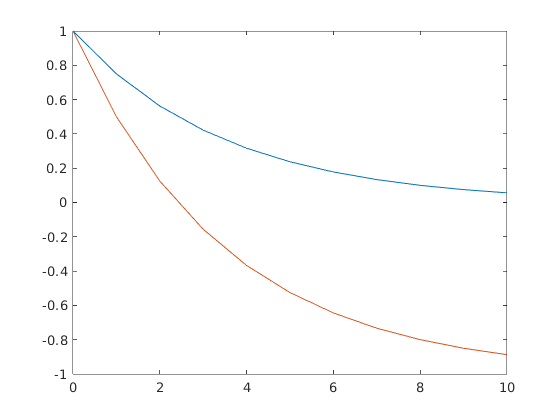



tspan = [0,10];
n= 10;


f = @(t,y) [-y(1)+y(2); -y(2)];
df = @(t,y) [-1,1;0,-1];



[t,y_out] = impl_euler(f,tspan,ya,n,df,tol,nmax);
plot(t,y_out)

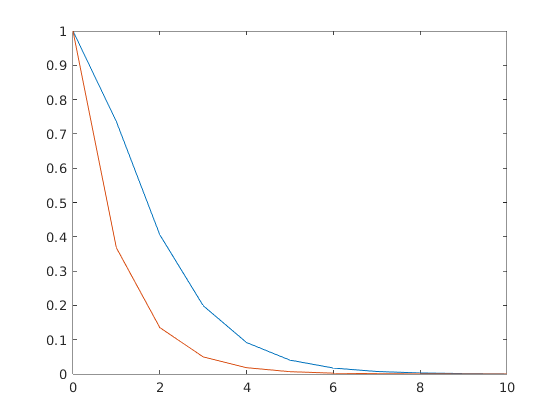


plot(t,f_loesung(t),t,f_loesung2(t))

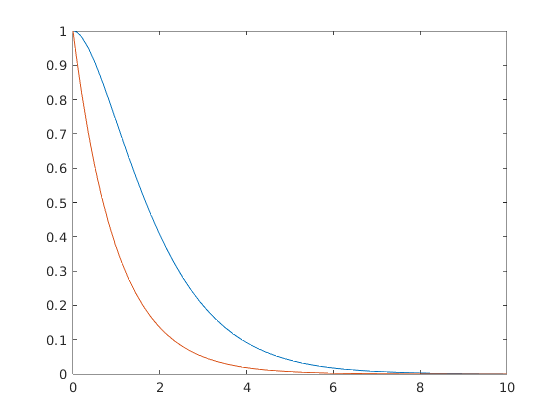


[t,y_ode] = ode45(f,tspan,ya);
plot(t,y_ode)

function [f,df] = f_beispiel(z)
    f = [-2*z(1)+z(2);-1-z(1)-z(2)];
    df = [-2,1;-1,-1];
end
